# Strong Connectivity and Kernel Graph Example

#### Source-Sink-Reacheable Digraph Example

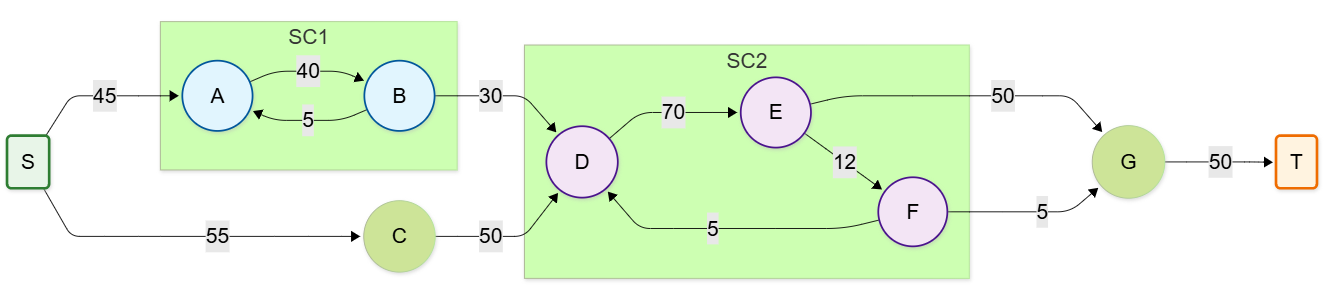

#### Weighted Adjacency Matrix

% Vertex: S(1), A(2), B(3), C(4), D(5), E(6), F(7), G(8), T(9)
E = [
% S  A  B  C  D  E  F  G  T
  0 45  0 55  0  0  0  0  0;  % S -> A, C
  0  0 40  0  0  0  0  0  0;  % A -> B  
  0  5  0  0 30  0  0  0  0;  % B -> A,D
  0  0  0  0 50  0  0  0  0;  % C -> D
  0  0  0  0  0 70  0  0  0;  % D -> E
  0  0  0  0  0  0 12 50  0;  % E -> F, G
  0  0  0  0  4  0  0  5  0;  % F -> D, G
  0  0  0  0  0  0  0  0 50;  % G -> T
  0  0  0  0  0  0  0  0  0;  % T (sink)
]

E =      0    45     0    55     0     0     0     0     0
     0     0    40     0     0     0     0     0     0
     0     5     0     0    30     0     0     0     0
     0     0     0     0    50     0     0     0     0
     0     0     0     0     0    70     0     0     0
     0     0     0     0     0     0    12    50     0
     0     0     0     0     5     0     0     5     0
     0     0     0     0     0     0     0     0    50
     0     0     0     0     0     0     0     0     0


#### Calculate thecnical coeficients matrix and consumptions

x=sum(E,2);
A=divideCol(E,x)

A =          0    1.1250         0    1.1000         0         0         0         0         0
         0         0    1.1429         0         0         0         0         0         0
         0    0.1250         0         0    0.4286         0         0         0         0
         0         0         0         0    0.7143         0         0         0         0
         0         0         0         0         0    1.1290         0         0         0
         0         0         0         0         0         0    1.2000    1.0000         0
         0         0         0         0    0.0714         0         0    0.1000         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


k=sum(A(:,2:end-1))

k =     1.2500    1.1429    1.1000    1.2143    1.1290    1.2000    1.1000


B=divideRow(E,x)

B =          0    0.4500         0    0.5500         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0    0.1429         0         0    0.8571         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0    0.1935    0.8065         0
         0         0         0         0    0.5000         0         0    0.5000         0
         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0         0         0         0         0         0


#### Calculate Spectral Ratio

rho = max(real(eig(A)));
fprintf('Spectral Ratio ρ(A) = %.4f\n', rho);

Spectral Ratio ρ(A) = 0.4591


nodeLabels = {'S', 'A', 'B', 'C', 'D', 'E', 'F', 'G', 'T'};

#### Compute Transitive Closure, Strong Components and Kernel Matrix

AA = logical(E);
TC=transitiveClosure(AA)

TC = 9×9 logical array
   1   1   1   1   1   1   1   1   1
   0   1   1   0   1   1   1   1   1
   0   1   1   0   1   1   1   1   1
   0   0   0   1   1   1   1   1   1
   0   0   0   0   1   1   1   1   1
   0   0   0   0   1   1   1   1   1
   0   0   0   0   1   1   1   1   1
   0   0   0   0   0   0   0   1   1
   0   0   0   0   0   0   0   0   1


SC=getStrongComponents(TC);
kM=getKernelMatrix(E,SC)

kM =      0    45    55     0     0     0
     0     0     0    30     0     0
     0     0     0    50     0     0
     0     0     0     0    55     0
     0     0     0     0     0    50
     0     0     0     0     0     0


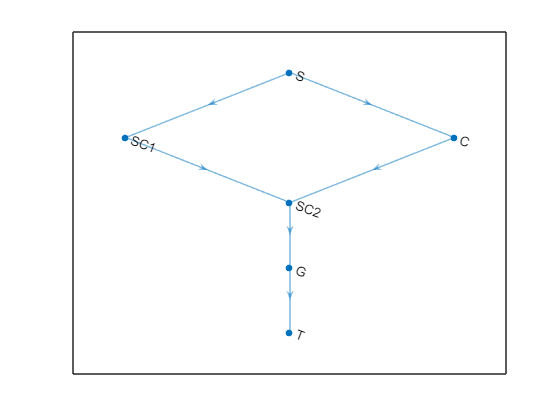

[kLabels,groupsTable]=getKernelLabels(SC,nodeLabels);
dg=digraph(kM,kLabels);
plot(dg);

disp(groupsTable')

    {'S'}    {'S'  }
    {'A'}    {'SC1'}
    {'B'}    {'SC1'}
    {'C'}    {'C'  }
    {'D'}    {'SC2'}
    {'E'}    {'SC2'}
    {'F'}    {'SC2'}
    {'G'}    {'G'  }
    {'T'}    {'T'  }



function SC=getStrongComponents(TC)
% Find the strongly connected components
% Return the membership matrix (nc,n)
    n=size(TC,1);
    grp=zeros(1,n); cnt=0;
    for u=1:n
        if ~grp(u)
            cnt=cnt+1;
            idx = TC(u,:) & TC(:,u)';  
            grp(idx)=cnt;
        end
    end
    SC=sparse(grp,1:n,true(n,1),cnt,n);
end

function kM=getKernelMatrix(A,SC)
    nc=size(SC,1);
    kM=SC*A*SC';
    kM(1:nc+1:end)=0;
end

function [kLabels,groupsTable]=getKernelLabels(SC,nodeLabels)
    [grp,~]=find(SC);
    [~,jdx,idx]=unique(grp);
    kLabels = nodeLabels(jdx);
    nrg = accumarray(idx,1);
    tmp = find(nrg>1);
    for i=1:length(tmp)
        kLabels{tmp(i)}=['SC',num2str(i)];
    end
    groupsTable=[nodeLabels;kLabels(idx)];
end